# Linear Transormations Examples

[Link to lecture notes](https://jonshiach.github.io/graphics-book/files/2.0_Transformations.html)

### Example 19 - Transformation matrix

A linear transformation $T:\mathbb{R}^2 \to \mathbb{R}^2$ is defined by $T: (x, y) \mapsto (3x + y, x + 2y)$. Calculate the transformation matrix and use it to calculate $T(1, 1)$.

T = @(u) [ 3 * u(1) + u(2) ; 
           u(1) + 2 * u(2)];

A = sym([T([1 ; 0]), T([0 ; 1])])

$$A = \left(\begin{array}{cc} 3 & 1\\ 1 & 2 \end{array}\right)$$

A * [1 ; 1]

$$ans = \left(\begin{array}{c} 4\\ 3 \end{array}\right)$$

### Example 20 - Transformation matrix from a set of images

Determine the transformation matrix $A$ for the linear transformation $T:\mathbb{R}^2 \to \mathbb{R}^2$ such that


$$T\pmatrix{ 1 \cr 1 } = \pmatrix{ 4 \cr 3 }, \qquad T\pmatrix{ 1 \cr 2 } = \pmatrix{ 5 \cr 5 }.$$


u1 = [1 ; 1];
u2 = [1 ; 2];
Tu1 = [4 ; 3];
Tu2 = [5 ; 5];

A = sym([Tu1, Tu2] * inv([u1, u2]))

$$A = \left(\begin{array}{cc} 3 & 1\\ 1 & 2 \end{array}\right)$$

### Example 21 - Inverse linear transformations

Determine the inverse of the transformation $T: \mathbb{R}^2 \to \mathbb{R}^2$ defined by $T(x, y) \mapsto (3 x + y, x + 2 y)$ and calculate $T^{-1}(4, 3)$.

T = @(v) [ 3 * v(1) + v(2) ; 
           v(1) + 2 * v(2) ];

A = sym([T([1 ; 0]), T([0 ; 1])]);
invA = inv(A)

$$invA = \left(\begin{array}{cc} \frac{2}{5} & -\frac{1}{5}\\ -\frac{1}{5} & \frac{3}{5} \end{array}\right)$$

invA * [4 ; 3]

$$ans = \left(\begin{array}{c} 1\\ 1 \end{array}\right)$$

### Example 22 - Composite linear transformations

Two linear transformations is defined as $T:(x, y, z) \mapsto (2 x + 4 y, -x + 3 y, x + 2 y)$ and $S:(x, y) \mapsto (2x + y - z, 3x + z, y - 2z)$.

(i) Determine the composite linear transformation $S \circ T(\mathbf{u})$ for $\mathbf{u} = (x, y, z)$.

T = @(v) [ 2 * v(1) + 4 * v(2) ; 
          -v(1) + 3 * v(2) ; 
          v(1) + 2 * v(2) ];

S = @(v) [ 2 * v(1) + v(2) - v(3) ; 
           3 * v(1) + v(3) ; 
           v(2) - 2 * v(3) ];

syms x y z
u = [x ; y ; z];
S(T(u))

$$ans = \left(\begin{array}{c} 2\,x+9\,y\\ 7\,x+14\,y\\ -3\,x-y \end{array}\right)$$

(ii) Determine the single transformation matrix $C$ that represents $S\circ T$.

A = [T([1 ; 0]), T([0 ; 1])];
B = [S([1 ; 0 ; 0]), S([0 ; 1 ; 0]), S([0 ; 0 ; 1])];

C = sym(B * A)

$$C = \left(\begin{array}{cc} 2 & 9\\ 7 & 14\\ -3 & -1 \end{array}\right)$$

(iii) Use your matrix $C$ to determine $S \circ T(\mathbf{u})$ for $\mathbf{u} = (x, y)$.

u = [x ; y];
C * u

$$ans = \left(\begin{array}{c} 2\,x+9\,y\\ 7\,x+14\,y\\ -3\,x-y \end{array}\right)$$

### Example 23 - Translation

A triangle is defined by three points with position vectors $\mathbf{p}_1 = (1, 0, 1)$, $\mathbf{p}_2 = (3, 0, 1)$ and $\mathbf{p}_3 = (2, 0, 3)$. The triangle is translated by the translation vector $\mathbf{t} = (3, 0, 1)$. Calculate the positions of the triangle vertices of the translated triangle.

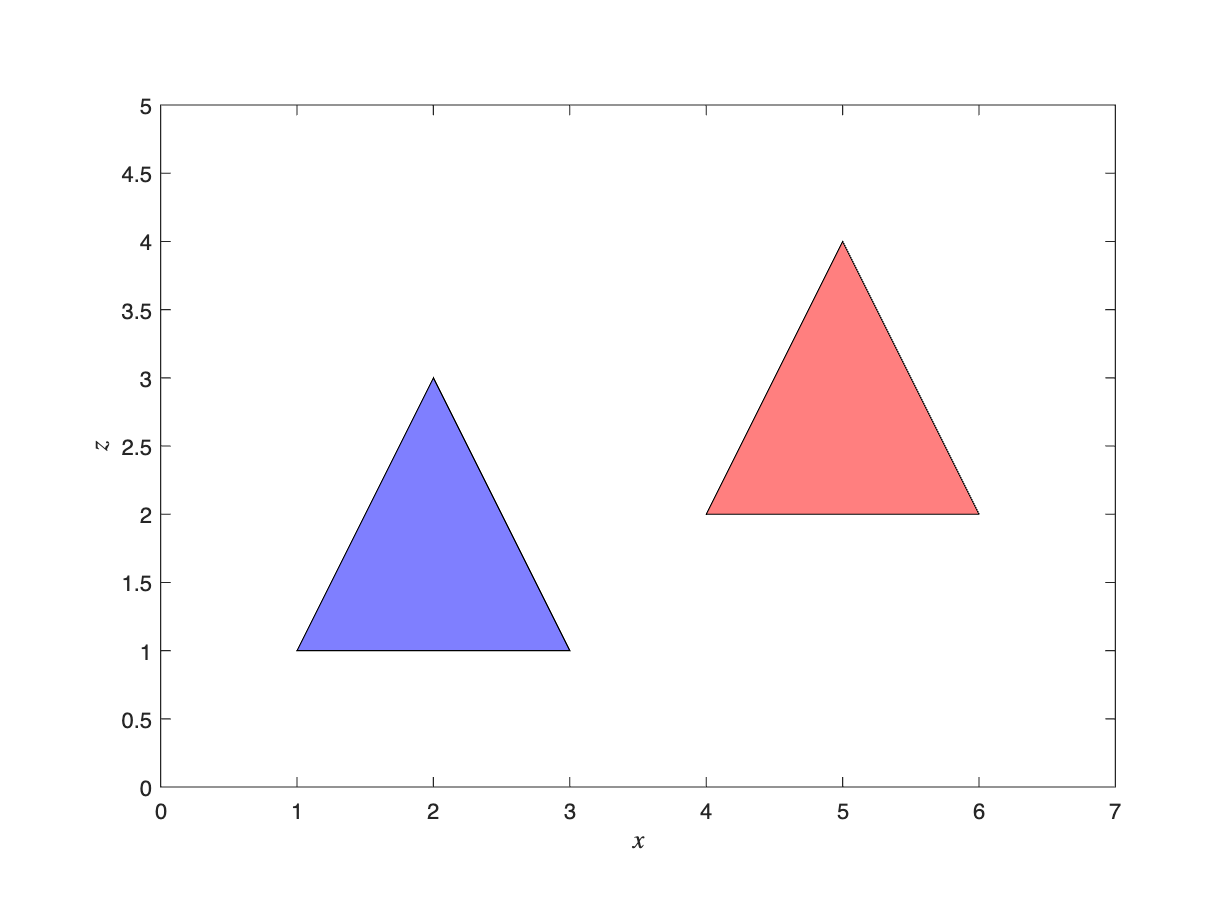

clear

% Define homogeneous co-ordinate matrix
P = [ 1, 3, 2 ;
      0, 0, 0 ;
      1, 1, 3 ;
      1, 1, 1 ];

% Define translation matrix 
T = @(t) [ 1, 0, 0, t(1) ; 
           0, 1, 0, t(2) ; 
           0, 0, 1, t(3) ; 
           0, 0, 0, 1 ];

% Apply translation
t = [3 ; 0 ; 1];
P1 = T(t) * P;

% Plot polygons
figure
patch(P(1,:), P(3,:), 'b', FaceAlpha=0.5)
patch(P1(1,:), P1(3,:), 'r', FaceAlpha=0.5)
axis equal
axis([0, 7, 0, 5])
xlabel("$x$", FontSize=12, Interpreter="latex")
ylabel("$z$", FontSize=12, Interpreter="latex")
box on

### Example 24 - Scaling

A polygon is defined by three points with position vectors $\mathbf{p}_1 = (1, 0, 1)$, $\mathbf{p}_2 = (3, 0, 1)$ and $\mathbf{p}_3 = (2, 0, 3)$. The polygon is scaled by a the scaling vector $\mathbf{s} = (3, 1, 2)$. Calculate the positions of the three points after the scaling has been applied.

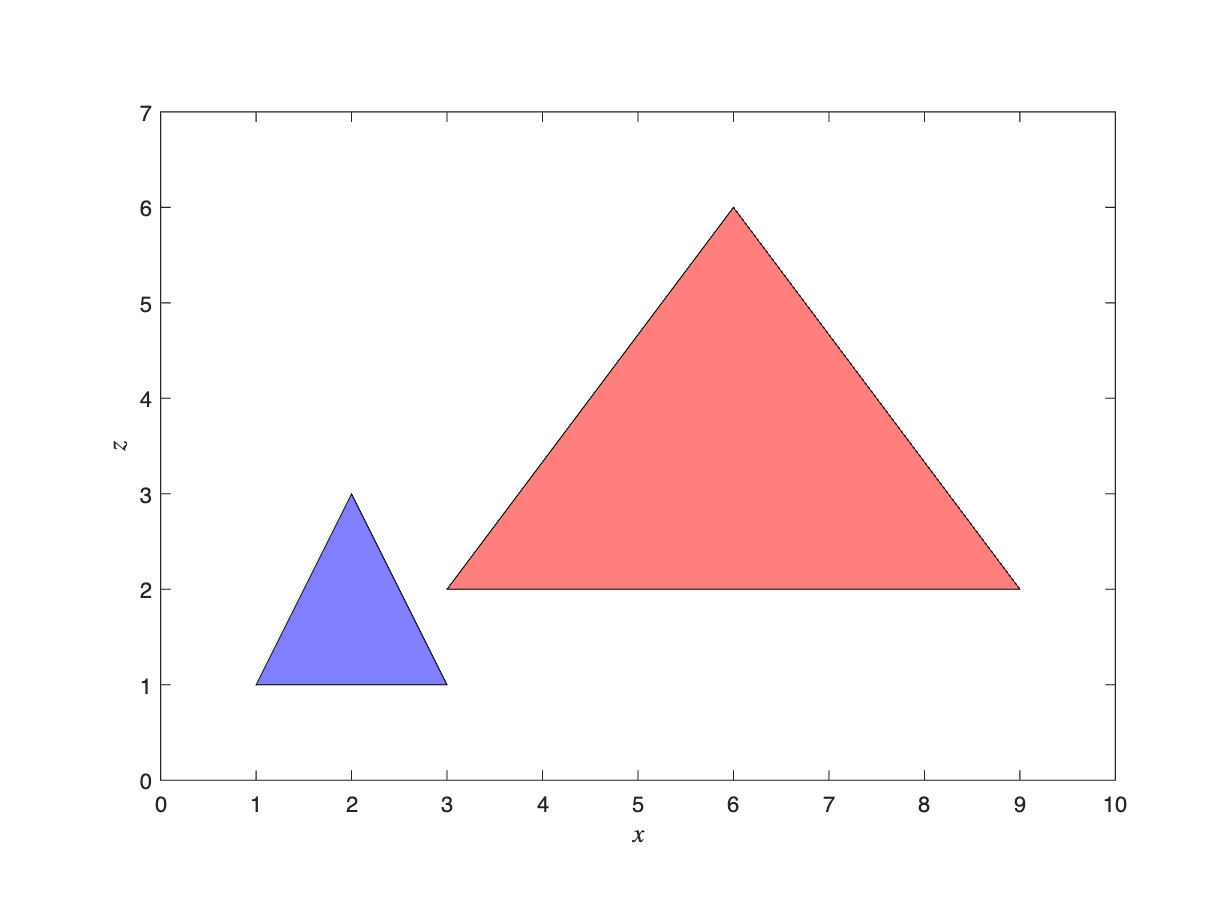

clear

% Define homogeneous co-ordinate matrix
P = [ 1, 3, 2 ;
      0, 0, 0 ;
      1, 1, 3 ;
      1, 1, 1 ];

% Define scaling matrix
S = @(s) [ s(1), 0, 0, 0 ; 
           0, s(2), 0, 0 ; 
           0, 0, s(3), 0 ; 
           0, 0, 0, 1 ];

% Apply scaling
s = [3 ; 1 ; 2];
P1 = S(s) * P;

% Plot polygons
figure
patch(P(1,:), P(3,:), 'b', FaceAlpha=0.5)
patch(P1(1,:), P1(3,:), 'r', FaceAlpha=0.5)
axis equal 
axis([0, 10, 0, 7])
xlabel("$x$", FontSize=12, Interpreter="latex")
ylabel("$z$", FontSize=12, Interpreter="latex")
box on

### Example 25 - Scaling about centre

Scale the polygon from example 24 by a factor of 2 in all three directions.

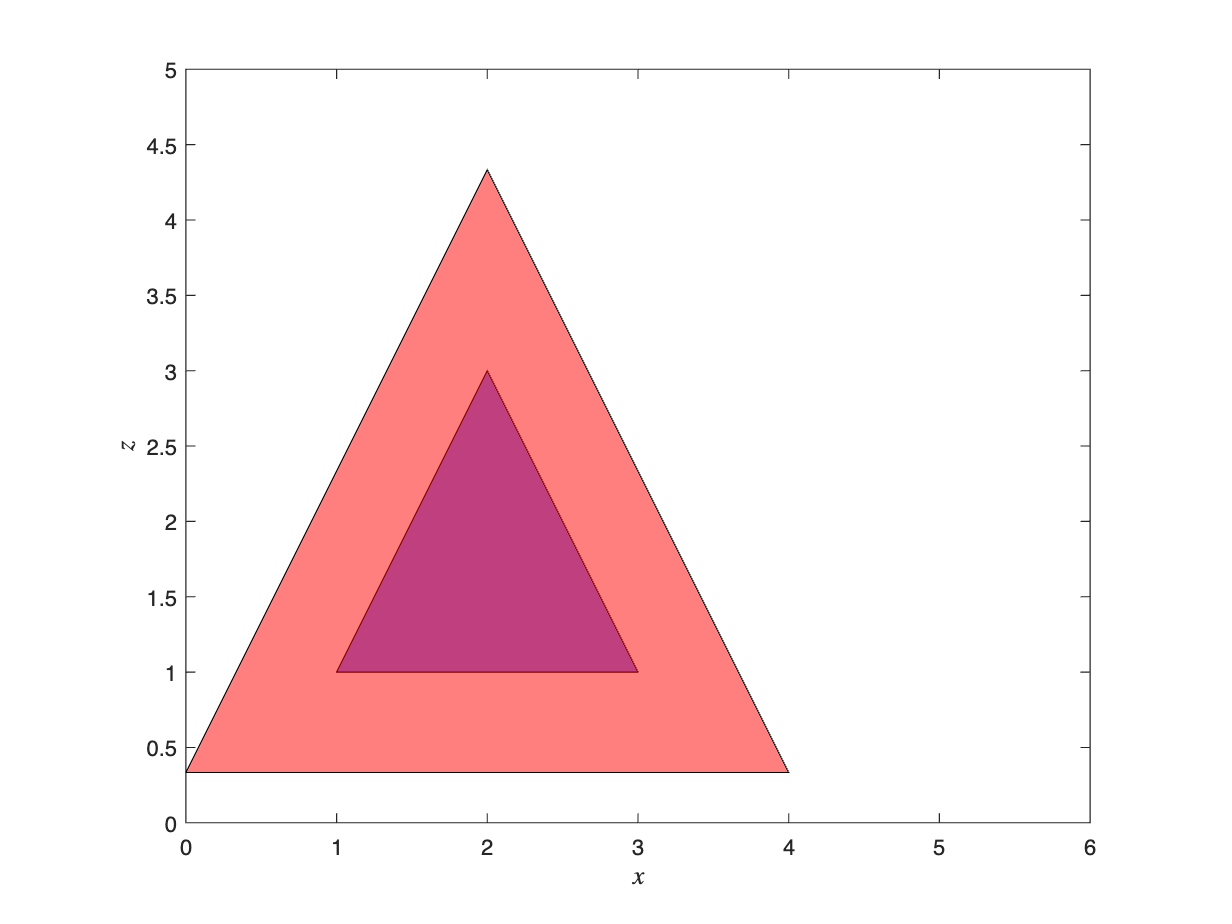

clear

% Define homogeneous co-ordinate matrix
P = [ 1, 3, 2 ;
      0, 0, 0 ;
      1, 1, 3 ;
      1, 1, 1 ];

% Calculate polygon centre
c = mean(P, 2);

% Define translation and scaling matrices
T = @(t) [ 1, 0, 0, t(1) ; 
           0, 1, 0, t(2) ; 
           0, 0, 1, t(3) ; 
           0, 0, 0, 1 ];

S = @(s) [ s(1), 0, 0, 0 ; 
           0, s(2), 0, 0 ; 
           0, 0, s(3), 0 ; 
           0, 0, 0, 1 ];

% Apply transformations
s = [2 ; 2 ; 2];
P1 = T(c) * S(s) * T(-c) * P;

% Plot polygons
figure
patch(P(1,:), P(3,:), 'b', FaceAlpha=0.5)
patch(P1(1,:), P1(3,:), 'r', FaceAlpha=0.5)
axis equal
axis([0, 6, 0, 5])
xlabel("$x$", FontSize=12, Interpreter="latex")
ylabel("$z$", FontSize=12, Interpreter="latex")
box on

### Example 26 - Rotation

A triangular polygon has vertices located at $\mathbf{p}_1 = (4, 1, 2)$, $\mathbf{p}_2 = (6, 1, 2)$ and $\mathbf{p}_3 = (5, 3, 2)$. The triangle is rotated by angle $\theta = \pi/4$ anti-clockwise about the $z$-axis. Calculate the positions of the vertices of the rotated triangle.

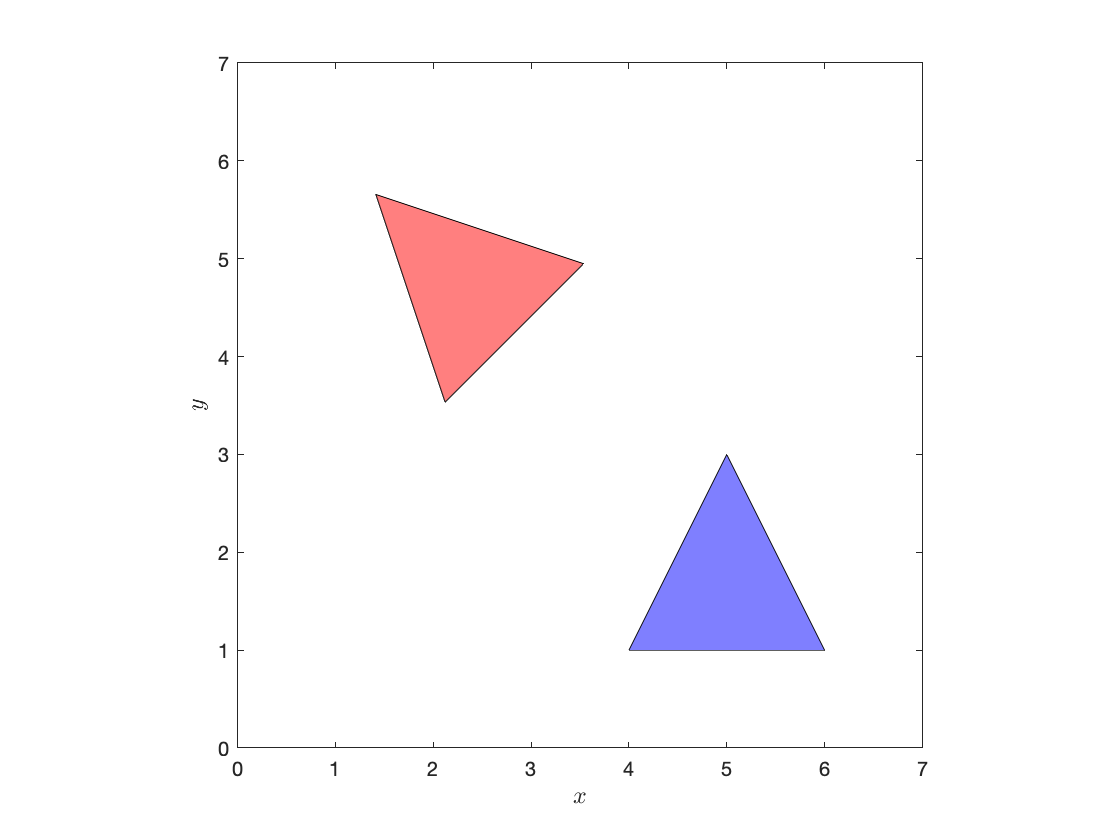

clear 

% Define homogeneous co-ordinate matrix
P = [ 4, 6, 5 ;
      1, 1, 3 ;
      2, 2, 2 ;
      1, 1, 1 ];


% Define rotation matrix
Rz = @(theta) [ cos(theta), -sin(theta), 0, 0 ; 
                sin(theta), cos(theta), 0, 0 ;
                0, 0, 1, 0 ;
                0, 0, 0, 1 ];

% Apply rotation
theta = pi / 4;
P1 = Rz(theta) * P;

% Plot polygons
figure
patch(P(1,:), P(2,:), 'b', FaceAlpha=0.5)
patch(P1(1,:), P1(2,:), 'r', FaceAlpha=0.5)
axis equal
axis([0, 7, 0, 7])
xlabel("$x$", FontSize=12, Interpreter="latex")
ylabel("$y$", FontSize=12, Interpreter="latex")
box on

### Example 27 - Rotation about centre

Rotate the polygon from example 26 by $\theta = \pi/4$ around the $z$-axis about its centre.

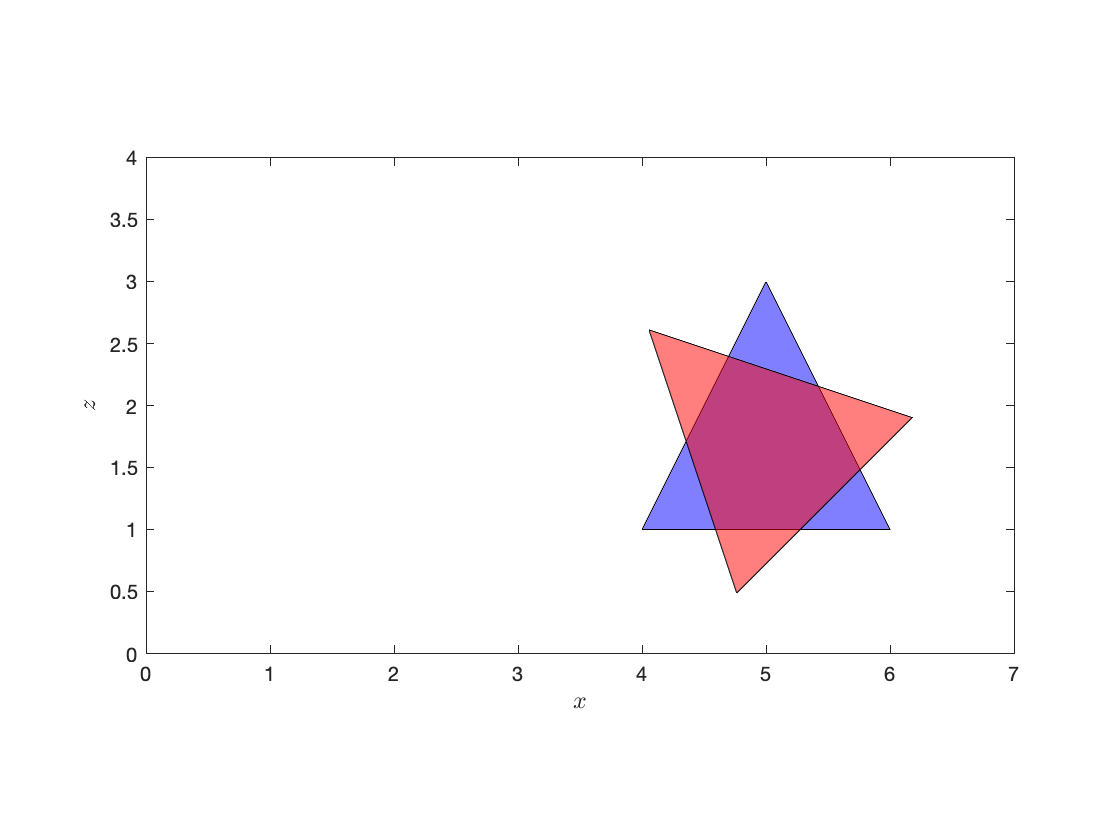

clear 

% Define homogeneous co-ordinate matrix
P = [ 4, 6, 5 ;
      1, 1, 3 ;
      2, 2, 2 ;
      1, 1, 1 ];

% Calculate polygon centre
c = mean(P, 2);

% Define translation, scaling and rotation matrices
T = @(t) [ 1, 0, 0, t(1) ; 
           0, 1, 0, t(2) ; 
           0, 0, 1, t(3) ; 
           0, 0, 0, 1 ];

S = @(s) [ s(1), 0, 0, 0 ; 
           0, s(2), 0, 0 ; 
           0, 0, s(3), 0 ; 
           0, 0, 0, 1 ];

Rz = @(theta) [ cos(theta), -sin(theta), 0, 0 ;  
                sin(theta), cos(theta), 0, 0 ;
                0, 0, 1, 0 ;
                0, 0, 0, 1 ];

% Apply transformations
theta = pi/4;
P1 = T(c) * Rz(theta) * T(-c) * P;

% plot polygons
figure
patch(P(1,:), P(2,:), 'b', FaceAlpha=0.5)
patch(P1(1,:), P1(2,:), 'r', FaceAlpha=0.5)
axis equal
axis([0, 7, 0, 4])
xlabel("$x$", FontSize=12, Interpreter="latex")
ylabel("$z$", FontSize=12, Interpreter="latex")
box on

### Example 28 - Rotation about a line

A flight simulation program is simulating the flight of an aeroplane positioned with its centre of mass at $\mathbf{c} = (10, 5, 50)$ travelling in the direction given by the vector $\mathbf{d} = (2, -1, -3)$. The user performs a roll of the plane by rotating about $\mathbf{d}$ by angle $\theta = \pi/6$ in the anti-clockwise direction. Calculate the composite transformation matrix that performs this action.

First translate $\mathbf{c}$ to the origin.

% Define translation matrix
T = @(t) [ 1, 0, 0, t(1) ; 
           0, 1, 0, t(2) ; 
           0, 0, 1, t(3) ; 
           0, 0, 0, 1 ];

% Translate c to the origin
c = [10 ; 5 ; 50];
sym(T(-c))

$$ans = \left(\begin{array}{cccc} 1 & 0 & 0 & -10\\ 0 & 1 & 0 & -5\\ 0 & 0 & 1 & -50\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Next rotate around the $z$-axis so that $\mathbf{d}$ is in the $xz$-plane.

d = [2 ; -1 ; -3];
d1 = sqrt(d(1)^2 + d(2)^2);

Rz = sym([ d(1) / d1, -abs(d(2)) / d1, 0, 0 ; 
           abs(d(2)) / d1,  d(1) / d1, 0, 0 ; 
           0,  0, 1, 0 ;
           0,  0, 0, 1 ])

$$Rz = \left(\begin{array}{cccc} \frac{2\,\sqrt{5}}{5} & -\frac{\sqrt{5}}{5} & 0 & 0\\ \frac{\sqrt{5}}{5} & \frac{2\,\sqrt{5}}{5} & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Check if $R_z$ is correct

Rz * [d ; 1]

$$ans = \left(\begin{array}{c} \sqrt{5}\\ 0\\ -3\\ 1 \end{array}\right)$$

The $y$ component is zero so $\mathbf{d}$ is now in the $xz$-plane. Next rotate around the $y$-axis so that $\mathbf{d}$ points along the $x$-axis.

Ry = sym([ d1 / norm(d), 0, -abs(d(3)) / norm(d), 0 ;
           0, 1,  0, 0 ;
           abs(d(3)) / norm(d), 0,  d1 / norm(d), 0 ;
           0, 0,  0, 1 ])

$$Ry = \left(\begin{array}{cccc} \frac{\sqrt{5}\,\sqrt{14}}{14} & 0 & -\frac{3\,\sqrt{14}}{14} & 0\\ 0 & 1 & 0 & 0\\ \frac{3\,\sqrt{14}}{14} & 0 & \frac{\sqrt{5}\,\sqrt{14}}{14} & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Check that $R_y$ is correct

Ry * Rz * [d ; 1]

$$ans = \left(\begin{array}{c} \sqrt{14}\\ 0\\ 0\\ 1 \end{array}\right)$$

Both the $y$ and $z$ components are zero so $\mathbf{d}$ now points along the $x$-axis. Next perform the rotation by $\theta = \pi/6$.

Rx = @(theta) [ 1, 0, 0, 0 ;
                0, cos(theta), -sin(theta), 0 ;
                0, sin(theta), cos(theta), 0 ;
                0, 0, 0, 1 ];

theta = pi / 6;
sym(Rx(theta))

$$ans = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & \frac{\sqrt{3}}{2} & -\frac{1}{2} & 0\\ 0 & \frac{1}{2} & \frac{\sqrt{3}}{2} & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$